clear

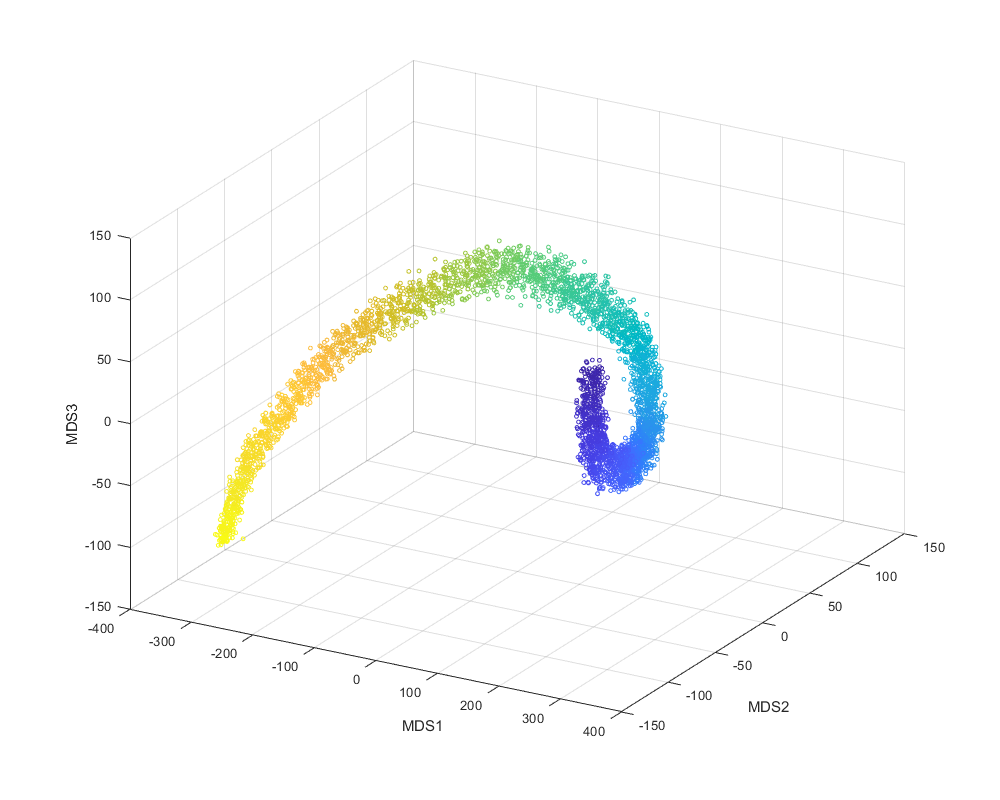

image_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a\BACKUP_3';
code_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a';
% imglist = ls([image_dir,'\block*.jpg']);
% codelist = ls([code_dir,'\block*.mat']);
imglist = dir(fullfile(image_dir, 'block*.jpg'));
img_fn = {imglist.name};

img_fullfn = fullfile(image_dir, {imglist.name});
codelist = dir(fullfile(code_dir, 'block*.mat'));
code_fn = {codelist.name};
code_fullfn = fullfile(code_dir, {codelist.name});

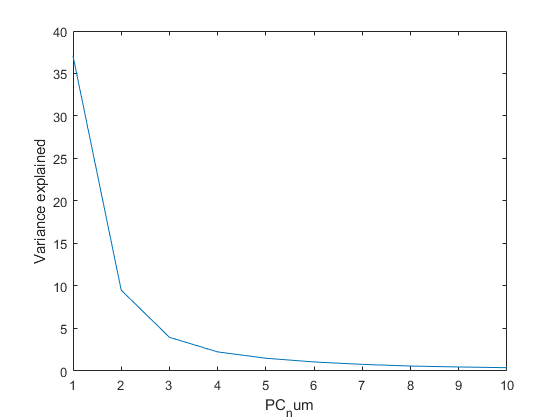

score_arr = [];
id_arr = {};
code_arr = [];
for i =1:numel(code_fullfn)
   data = load(code_fullfn{i});

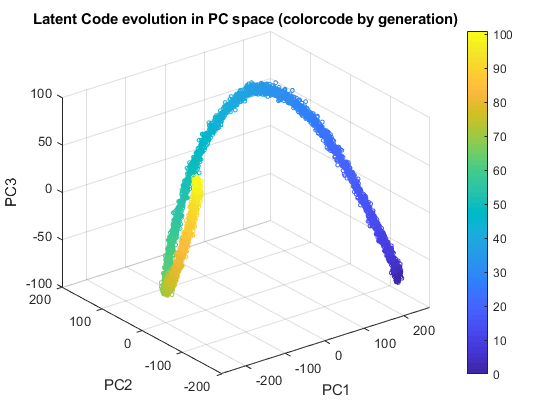

   code_arr = cat(1, code_arr, data.codes);
   id_arr = cat(2, id_arr, data.ids);
   if i~=1
       score_arr = cat(1, score_arr, data.scores);
   end
   if i == numel(code_fullfn)
       score_arr = cat(1, score_arr, nan([length(data.ids), 1]));
   end

end
generation_id = ceil( ((1:size(code_arr,1)) - 30 + 1)/40);

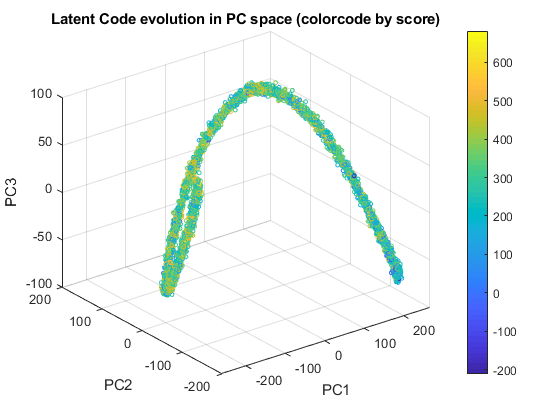

tic
code_dist = pdist(code_arr);
toc
tic
code_coord3 = mdscale(code_dist, 3);
toc % Elapsed time is 2374.430649 seconds.


figure('Position',[0,0,1000,800])
scatter3(code_coord3(:,1),code_coord3(:,2),code_coord3(:,3),9,generation_id)
xlabel("MDS1")
ylabel("MDS2")
zlabel("MDS3")
view([30 29])

save('dimen_red_coord.mat','code_coord3','-append')

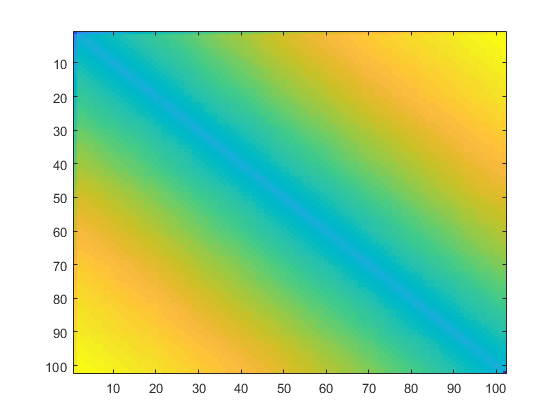

[PC_axiss,code_PC,PC_var,~,var_explained] = pca(code_arr,'NumComponents',10);

figure()
plot(var_explained(1:10))
title("PC_explained_var")
ylabel("Variance explained")
xlabel("PC_num")

figure(2)%'Position',[0,0,1000,800]

Elapsed time is 10.635254 seconds.


scatter3(code_PC(:,1),code_PC(:,2),code_PC(:,3),9,generation_id)
xlabel("PC1")
ylabel("PC2")

img_dist_mat =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

zlabel("PC3")
colorbar()
title("Latent Code evolution in PC space (colorcode by generation)")

Error using norm
First argument must be single or double.

figure(3)%'Position',[0,0,1000,800]
scatter3(code_PC(:,1),code_PC(:,2),code_PC(:,3),9,score_arr)
xlabel("PC1")
ylabel("PC2")
zlabel("PC3")
colorbar()
title("Latent Code evolution in PC space (colorcode by score)")

save('dimen_red_coord.mat','code_PC','-append')

code_dist_mat = squareform(code_dist);
group_dist_matrix()

figure()
imagesc(group_dist_mat)
xlabel("generation_id")
ylabel("generation_id")
title("")

tic
imgs = {};
img_arr = [];
for i = 1:numel(img_fullfn)
    imgs{i} = imread(img_fullfn{i});
    %img_arr = cat(1, img_arr, imgs{i}(:)');
end
toc

tic
img_dist_mat = zeros(numel(imgs))
for i = 1:numel(imgs)
    for j = i+1:numel(imgs)
        img_dist_mat(i,j) = norm(single(imgs{j}(:) - imgs{i}(:)));
        img_dist_mat(j,i) = img_dist_mat(i,j); 
    end
end
img_group_dist_mat = group_dist_matrix(img_dist_mat, generation_id);
toc

function group_dist_mat = group_dist_matrix(code_dist_mat, generation_id)
groups = unique(generation_id);
group_dist_mat = zeros(numel(groups));
for i = 1:numel(groups)
    for j = 1:numel(groups)
        id_i = groups(i);
        id_j = groups(j);
        group_dist_mat(i,j) = mean(code_dist_mat(generation_id==id_i, generation_id==id_j),"all");
    end
end
end